#### LQR

Gli autovalori della matrice dinamica del sistema determinano i modi di evoluzione del sistema a ciclo chiuso. Con la tecnica del pole placement è possibile posizionare tali autovalori in posizioni arbitrarie del piano complesso in base alle esigenze. Piuttosto che posizionare gli autovalori rispetto a $\zeta ,\omega_n$, una scelta alternativa è quella di posizionarli cercando di ottimizzare determinate performance: LQR permette di ottenere i guadagni di un controllore state-feedback proprio attraverso una procedura di ottimizzazione di una funzione di costo quadratica. Lineare è il vincolo del nostro problema di ottimizzazione, quadratico è l'indice di performance (quadratico sia nello stato che nell'ingresso di controllo) che vogliamo minimizzare. 

$min_ {u(\cdot)} \tilde J \space \\s.t \space \dot x = Ax + Bu$, in cui $\tilde J = \int_{0}^{\infty} x^T Q_x x + u^T Q_u udt$ e rappresenta l'indice di performance cumulativo. 

In questa tecnica il passo chiave che il progettista deve effettuare è la scelta delle matrici $Q_x \space e \space Q_u
$ che devono essere definite positive per questioni di convergenza dell'equazione di Riccati. Tali matrici sono rispettivamente legate al task di controllo ed allo sforzo di controllo e sono fondamentali per ottenere un buon trade-off tra le performance del sistema e lo sforzo di controllo necessario ad ottenere tali prestazioni. Ciò che è rilevante non è il valore numerico di $Q_x \space e \space Q_u
$ , ma il loro rapporto relativo. 

#### Passi progettuali

- **Raggiungibilità** : La matrice di raggiungibilità è una matrice che rappresenta la capacità di guidare il sistema da uno stato iniziale arbitrario a uno stato desiderato attraverso l'uso dell'ingresso di controllo. Questa è definita come : $W_R = [B ; AB; A^2 B; A^3B; ...; A^n B] $. Il sistema quindi è raggiungibile se e solo se la matrice di raggiungibilità è di rango completo, cioè se la sua dimensione è uguale all'ordine del sistema.

- **Scegliamo **$Q_x \space e \space Q_u$ 

- **Trovo **$K$: $k = lqr (A,B, Q_x, Q_u)$

#### *Linearizzazione*

Il sistema dinamico non lineare è descritto nella forma:


$$\dot x_1 = x_2 = f_1(x_1,x_2)
\\\dot x_2= -\frac {g}{l} sin(x_1) - \frac {b}{ml^2} x_2 + \frac{u(t)}{ml^2} = f_2(x_1,x_2)$$


Si calcolano i punti di equilibrio ponendo le due equazioni uguali a 0:


$$\left\{
\begin{array}{l} x_2 = 0
\\sin(x_1)= 0
\end{array}
\right.$$


I punti di equilibrio risultanti sono: $$x_A= \left[\matrix{ 0 \cr 0} \right]$ e $$x_B= \left[\matrix{ \pi \cr 0} \right]$.  Nel caso in esame è di interessa linearizzare intorno al punto di equilibrio $$x_e=x_B$$

Siano $$z=x-x_e$$ e $$v=u-u_e$$, con $x_e= \left[ \matrix{\pi \cr 0} \right]$ e $$u_e=0$
$, il sistema verrebbe riscritto come segue:

$\left\{
\begin{array}{l} \dot{z_1} =z_2
\\ \dot{z_2}=-\frac{g}{l}sin(z_1+x_{e_1})-\frac{b}{ml^2}z_2+\frac{v(t)}{ml^2}
\end{array}
\right.$ con $v(t)$ ingresso di controllo del sistema linearizzato.

La linearizzazione del sistema intorno al punto di equilibrio, richiede di trovare le matrici $$A,B,C,D$$, rispetto al punto di equilibrio desiderato. Si procede quindi col calcolo della matrice jacobiana:


$$J=\left[ \matrix{ \frac{df_1}{dz_1} & \frac{df_1}{dz_2} \cr\frac{df_2}{dz_1} & \frac{df_2}{dz_2} }\right]



= \left[ \matrix{ 0 & 1 \cr -\frac{g}{l}cos(z_1+x_{e_1}) & -\frac {b}{ml^2} }\right]_{|{z=z_A}}= \left[\matrix{0 & 1 \cr 9.81 & -0.1 } \right] = A$$


Il controllore del sistema linearizzato è quindi espresso come:

$ $v=-Kz+k_r r_l,$$  dove $r_l$ è il riferimento nella versione linearizzata del sistema. Antitrasformando, dunque, si ottiene:

 $$u-u_e=-K(x-x_e)+k_r(r_{nl}-\pi)$$, l'offset di $\pi$ nel termine che moltiplica $k_r$ è dovuto alla differenza di riferimento tra il sistema linearizzato intorno a $$x_B= \left[\matrix{ \pi \cr 0} \right]$ e il sistema non lineare. Si può dedurre, quindi, che inseguire il riferimento nullo nella versione linearizzata del sistema porta a inseguire il riferimento desiderato nel sistema NL.

Per il caso in esame, a valle di quanto detto, l'ingresso di controllo è:


$$u=-K_1x_1+K_1x_{e_1}-K_2x_2+K_2x_{e_2}+k_r(r_{nl}-\pi)+u_e$$


nel quale sostituendo l'ingresso di equilibrio $$u_e=0$$ e dato che da specifiche $$r_{nl}=\pi$$si ottiene che:


$$u=-K_1x_1-K_2x_2+K_1\pi$$


clear, close all, clc
mkdir ('Risultati LQR')

%% Linearizzazione
m = 1; 
l = 1;
b = 0.1; 
g = 9.81;
% Matrici del sistema lineare
A=[0 1; g/l -b/(m*l^2)]

A =          0    1.0000
    9.8100   -0.1000


B=[0; 1/(m*l^2)]

B =      0
     1


C= [1 0]

C =      1     0


D= 0

D = 0

#### Verifica della raggiungibilità

In questo passaggiamo abbiamo verificato la raggiungibilità del sistema. Poichè il rango risulta pieno allora il sistema risulta essere raggiungibile


Wr = [B A*B]

Wr =          0    1.0000
    1.0000   -0.1000


r=rank(Wr)

r = 2

% Il rango è pieno quindi il sistema è raggiungibile

% Il sistema è stato linearizzato intorno al punto di equilibrio instabile
x1_e=pi

x1_e = 3.1416

x2_e = 0

x2_e = 0

x_e=[x1_e;x2_e]

x_e =     3.1416
         0


Scegliamo le due matrici $Q_x ,Q_u$ diagonali e ciò consente non solo di semplificare i calcoli ma anche di dare una diversa importanza ai vari stati: non a caso infatti il termine che pesa lo stato $x_1$ ha un peso maggiore rispetto a quello relativo ad $x_2$ in quanto il primo equivale all'uscita del sistema. La taratura delle due matrici è realizzata cercando di ottenere delle performance abbastanza "spinte" avendo però uno sforzo di controllo che rientri nei limiti del realistico e non sia troppo oneroso.

Qx=[ 10 0; 0 0.1];
Qu= 0.015;

% Qz=[ 20 0; 0 0.08];
% Qu= 0.003;


[K,S,P] = lqr(A,B,Qx,Qu);

Estrazione del guadagno proporzionale e visualizzazione dei risultati

Kr = 0;% guaranteeing reference regulation
K

K =    37.4307    8.9298


S

S =     3.7559    0.5615
    0.5615    0.1339


P

P =   -4.5149 + 2.6900i
  -4.5149 - 2.6900i


#### Simulazione e plot

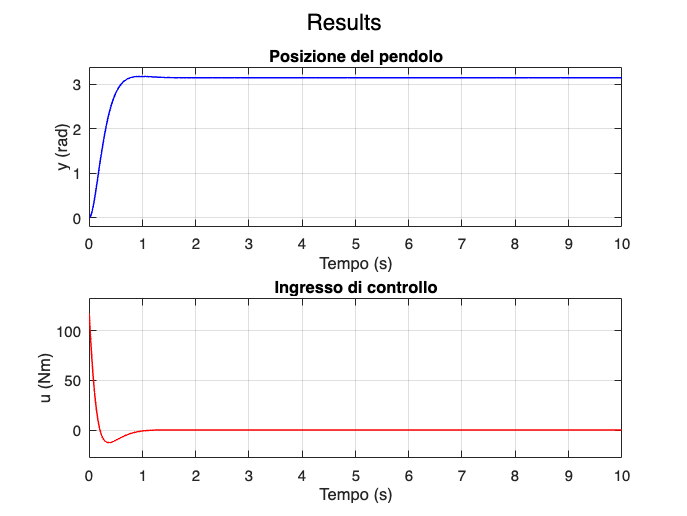

data =sim("LQR_Simulink.slx");
plot_data(data)
saveas(gcf, 'Risultati LQR/plot_result.png');

#### Analisi

results=stepinfo(data.y,data.t);
disp('Step Information for the Output');

Step Information for the Output


disp(results);

         RiseTime: 0.4262
    TransientTime: 0.6677
     SettlingTime: 0.6677
      SettlingMin: 2.8323
      SettlingMax: 3.1740
        Overshoot: 1.0313
       Undershoot: 0
             Peak: 3.1740
         PeakTime: 0.9603

